## Pre-process data

### Create folders for saving data for training, validation and testing

if ~exist('train','dir') 
    mkdir train 
end
if ~exist('val','dir') 
    mkdir val 
end
if ~exist('test','dir') 
    mkdir test 
end

### Pre-process Training data

Load training data (X_train)

load child_mind_x_train_2s_24chan_raw.mat

% number of training samples (each sample = 24 x 256 size)
num_train = size(X_train,3);

Load training labels (Y_train) which contains 4 columns: Subject_ID,  Sex (1 = Female, 0 = Male), Age, EHQ_Total (+100 = Fully Right-Handed, -100 = Fully Left-Handed)

load child_mind_all_labels_train_2s_24chan_raw.mat

Choose the 2nd column (Sex of the Subject) as Labels

train_labels = string(Y_train(:,2)); 

Convert the .mat training samples to .tif images

cd train;
mat2tiff(X_train,train_labels,num_train)
cd ..

Create training imageDatastore

train_imds = imageDatastore('train',...
"IncludeSubfolders",true,"FileExtensions",".tif","LabelSource","foldernames");


### Pre-process Validation data

Load validation data (X_val)


load child_mind_x_val_2s_24chan_raw.mat 

% num of validation samples
num_val = size(X_val,3); 

Load validation labels (Y_val)

load child_mind_all_labels_val_2s_24chan_raw.mat 
val_labels = string(Y_val(:,2));

Convert validation samples to tiff images

cd val;
mat2tiff(X_val,val_labels,num_val)
cd ..

Create validation datastore

val_imds = imageDatastore('val',...
"IncludeSubfolders",true,"FileExtensions",".tif","LabelSource","foldernames");


## Load the network layers to be trained

load('R-VGG_noNormalization.mat')
%deepNetworkDesigner


## Define training settings

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',20, ...
    'MiniBatchSize',70, ...
    'Plots','training-progress',...
     'ValidationData',val_imds);



## Train the network

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:10 |       40.00% |       50.14% |       1.8865 |       6.1317 |          0.0005 |
|       1 |          50 |       00:02:36 |       52.86% |       60.01% |       0.8094 |       0.8795 |          0.0005 |
|       1 |         100 |       00:03:58 |       58.57% |       58.96% |       0.7055 |       0.7687 |          0.0005 |
|       1 |         150 |       00:05:22 |       77.14% |       61.80% |       0.5860 |       0.7615 |          0.0005 |
|       

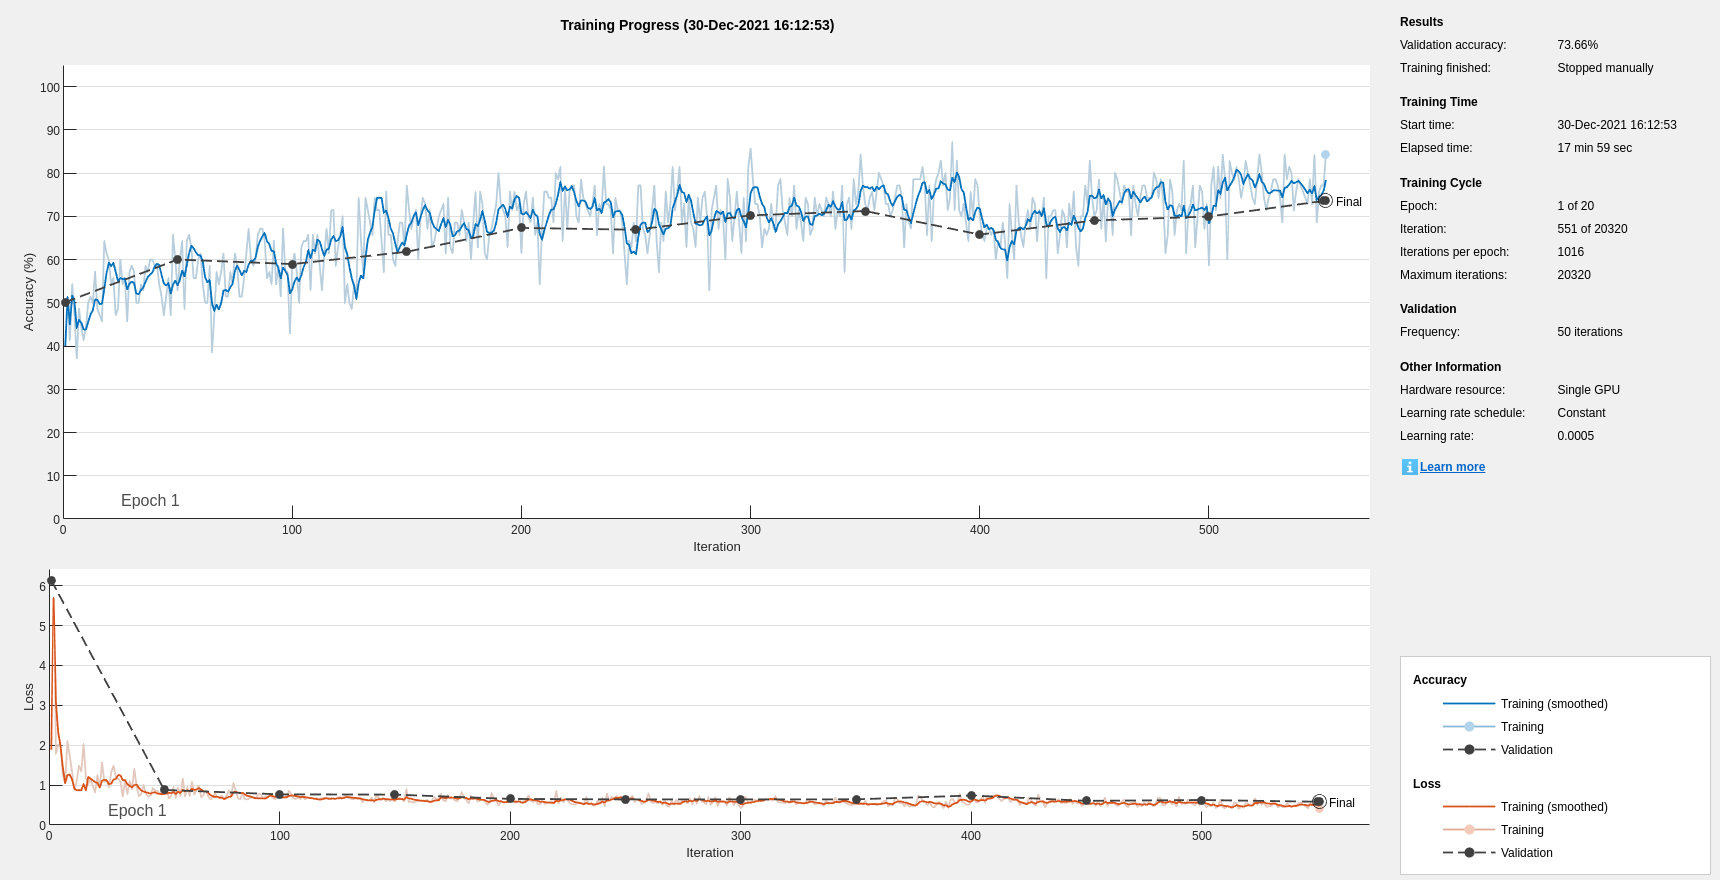

tiff_net = trainNetwork(train_imds,layers,options);


% Training on single GPU.
% |======================================================================================================================|
% |  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
% |         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
% |======================================================================================================================|
% |       1 |           1 |       00:00:56 |       44.29% |       50.15% |       1.2143 |       1.9437 |          0.0005 |
% |       1 |          50 |       00:02:29 |       55.71% |       51.82% |       0.6909 |       0.7110 |          0.0005 |
% |       1 |         100 |       00:03:57 |       52.86% |       60.45% |       0.6781 |       0.7265 |          0.0005 |
% |       1 |         150 |       00:05:40 |       70.00% |       61.81% |       0.6392 |       0.7193 |          0.0005 |
% |       1 |         200 |       00:07:27 |       54.29% |       60.36% |       0.6848 |       0.7320 |          0.0005 |
% |       1 |         250 |       00:08:59 |       65.71% |       70.58% |       0.6053 |       0.6268 |          0.0005 |
% |       1 |         300 |       00:10:34 |       80.00% |       72.51% |       0.4744 |       0.5956 |          0.0005 |
% |       1 |         350 |       00:12:02 |       81.43% |       72.70% |       0.4493 |       0.6074 |          0.0005 |
% |       1 |         400 |       00:13:30 |       77.14% |       73.38% |       0.4775 |       0.5731 |          0.0005 |
% |       1 |         450 |       00:14:56 |       78.57% |       74.92% |       0.3982 |       0.5894 |          0.0005 |
% |       1 |         451 |       00:14:57 |       80.00% |              |       0.5647 |              |          0.0005 |
% |======================================================================================================================|
% Training finished: Stopped manually.



### Pre-process Test data

Load training data (X_test)

load child_mind_x_test_2s_24chan_raw.mat

% num of test samples
num_test = size(X_test,3);

Load training labels (Y_test)

load child_mind_all_labels_test_2s_24chan_raw.mat

test_labels = string(Y_test(:,2));

Convert test samples to tif files

cd test
mat2tiff(X_test,test_labels,num_test)
cd ..

Create test datastore: test_imds

test_imds = imageDatastore('test',...
"IncludeSubfolders",true,"FileExtensions",".tif","LabelSource","foldernames");

## Test the trained network

Y_pred = classify(tiff_net,test_imds);
% Y_pred_label = test_imds.Labels;

%Test accuracy
correct = 0;
for i = 1 : num_test
    if(Y_pred(i)==test_imds.Labels(i))
        correct = correct+1;
    end
end

test_accuracy = 100*correct/num_test

test_accuracy = 75.2653



% test_accuracy =
% 
%    75.4851